addpath Datastore;

startup;

i = imread('GAL010_00142.jpg');

imshow(i)

imwrite(i,'image1.tif')

RUN_GUI

clear all

load image1_GTOutput_20190726T104846.mat;

imwrite(output.groundTruth.matrix,'groundtruth.tif','tiff')


inputs.IMAGE = 'image1.tif';
inputs.GRNDTRUTH = 'groundtruth.tif';
inputs.nclasses  = 4;    % number of classes
inputs.crossval  = 1;    % 1 = k-fold cross validation; 0,[] = none.
inputs.thresh    = [];   % 100,[] = no threshold; alph = alpha% chi^2 c.i.
inputs.prefilt   = 1;    % [] or 0 = no prefilt, 1 = 1st, 2 = 2nd, 3 = 3rd 
                         % order neighborhoods
inputs.smoothing = 3;    % 0,[] = none; 1 = nonlin filter; 2 = PLR; 3 = MRF
inputs.iter      = 5;    % # iters in PLR or MRF.
inputs.beta      = 10;   % beta (regularization parameter) for MRF.

tic
outputs = ImageClassify(inputs);

10 PERCENT RANDOM REMOVAL CROSS VALIDATION.
Percent misclassified after 10 removals = 5.5687
MRF iter = 1
MRF iter = 2
MRF iter = 3
MRF iter = 4
MRF iter = 5


toc

Elapsed time is 98.558170 seconds.


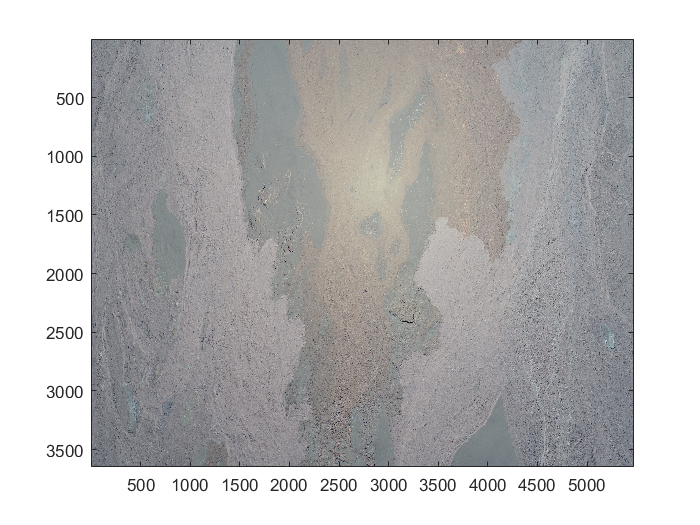

Image = outputs.Image;
GrndTruth = outputs.GrndTruth;
Classification = outputs.Classification;

if isempty(inputs.thresh)==1
    inputs.thresh = -1;
end
if 0<inputs.thresh && inputs.thresh<100
    inputs.nclasses=inputs.nclasses+1;
end

figure(1)
    imagesc(Image)

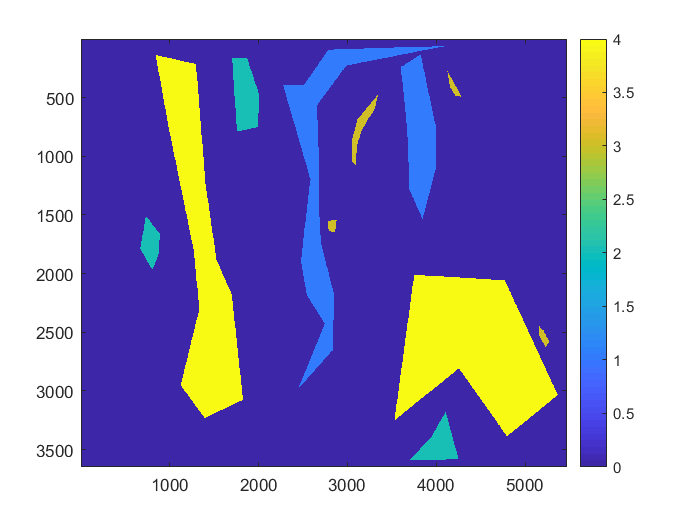

figure(2)
    imagesc(GrndTruth)
    colorbar, caxis([0,inputs.nclasses]) 

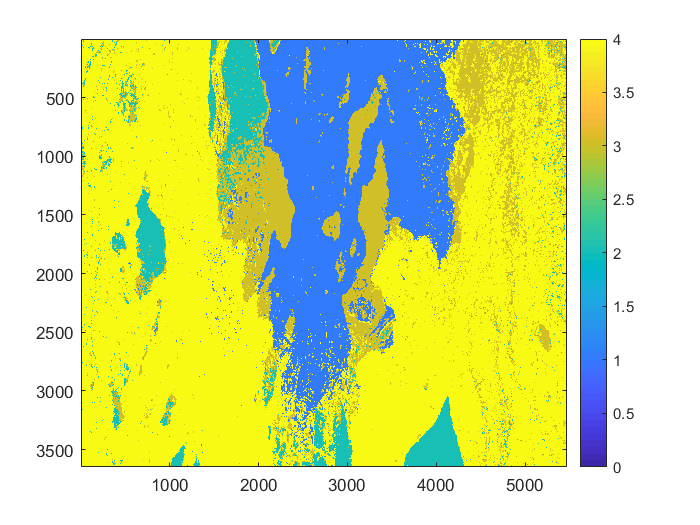

figure(3)
    imagesc(Classification)
    colorbar, caxis([0,inputs.nclasses]) 

% save image 
% compare image to previous
% also test examples using different values for beta